# **Apoyo en el desarrollo del Proyecto de Grado MIACON**

[MÓDULO 2: Identificación y control de una planta de primer orden](https://sites.google.com/view/miacon-proyectodegrado/gu%C3%ADas-de-laboratorio/m%C3%B3dulo-2-identificaci%C3%B3n-y-control-de-una-planta-de-primer-orden)

- `Hecho por:`` Diego Andrés García Díaz.`

- `Código:`` 2195533.`

- `Fecha:`` 15/10/2025.`

- `Asignatura:`` Control II (Adelanto de Nota).`

## Módelo para un Sitema Térmico (Primer Orden)

### $G_P \left(\mathcal{s}\right)=\frac{K_p }{T_{\textrm{p1}} \cdot \mathcal{s}+1}\cdot e^{-T_d \cdot \mathcal{s}}$;

### $G_P \left(\mathcal{s}\right)=\textrm{Actuador}+\textrm{Planta}+\textrm{Sensor}$;

### $K=K_p =\textrm{Ganancia}$; 

$K=\frac{\Delta Y\;\left(\textrm{salida}\right)}{\Delta U\;\left(\textrm{entrada}\right)}$**;**

### ${T=\;T}_{\textrm{p1}} =\textrm{Constante}\;\textrm{de}\;\textrm{tiempo}$; 

$T=\frac{3}{2}\left(t_2 -t_1 \right)$**;**

### ${L=\;T}_d =\textrm{Tiempo}\;\textrm{muerto}\;\left(\textrm{Delay}\right)$ ;


$$L=t_2 -T$$


## Modelo identificado siguiendo las instrucciones de la página web:

## 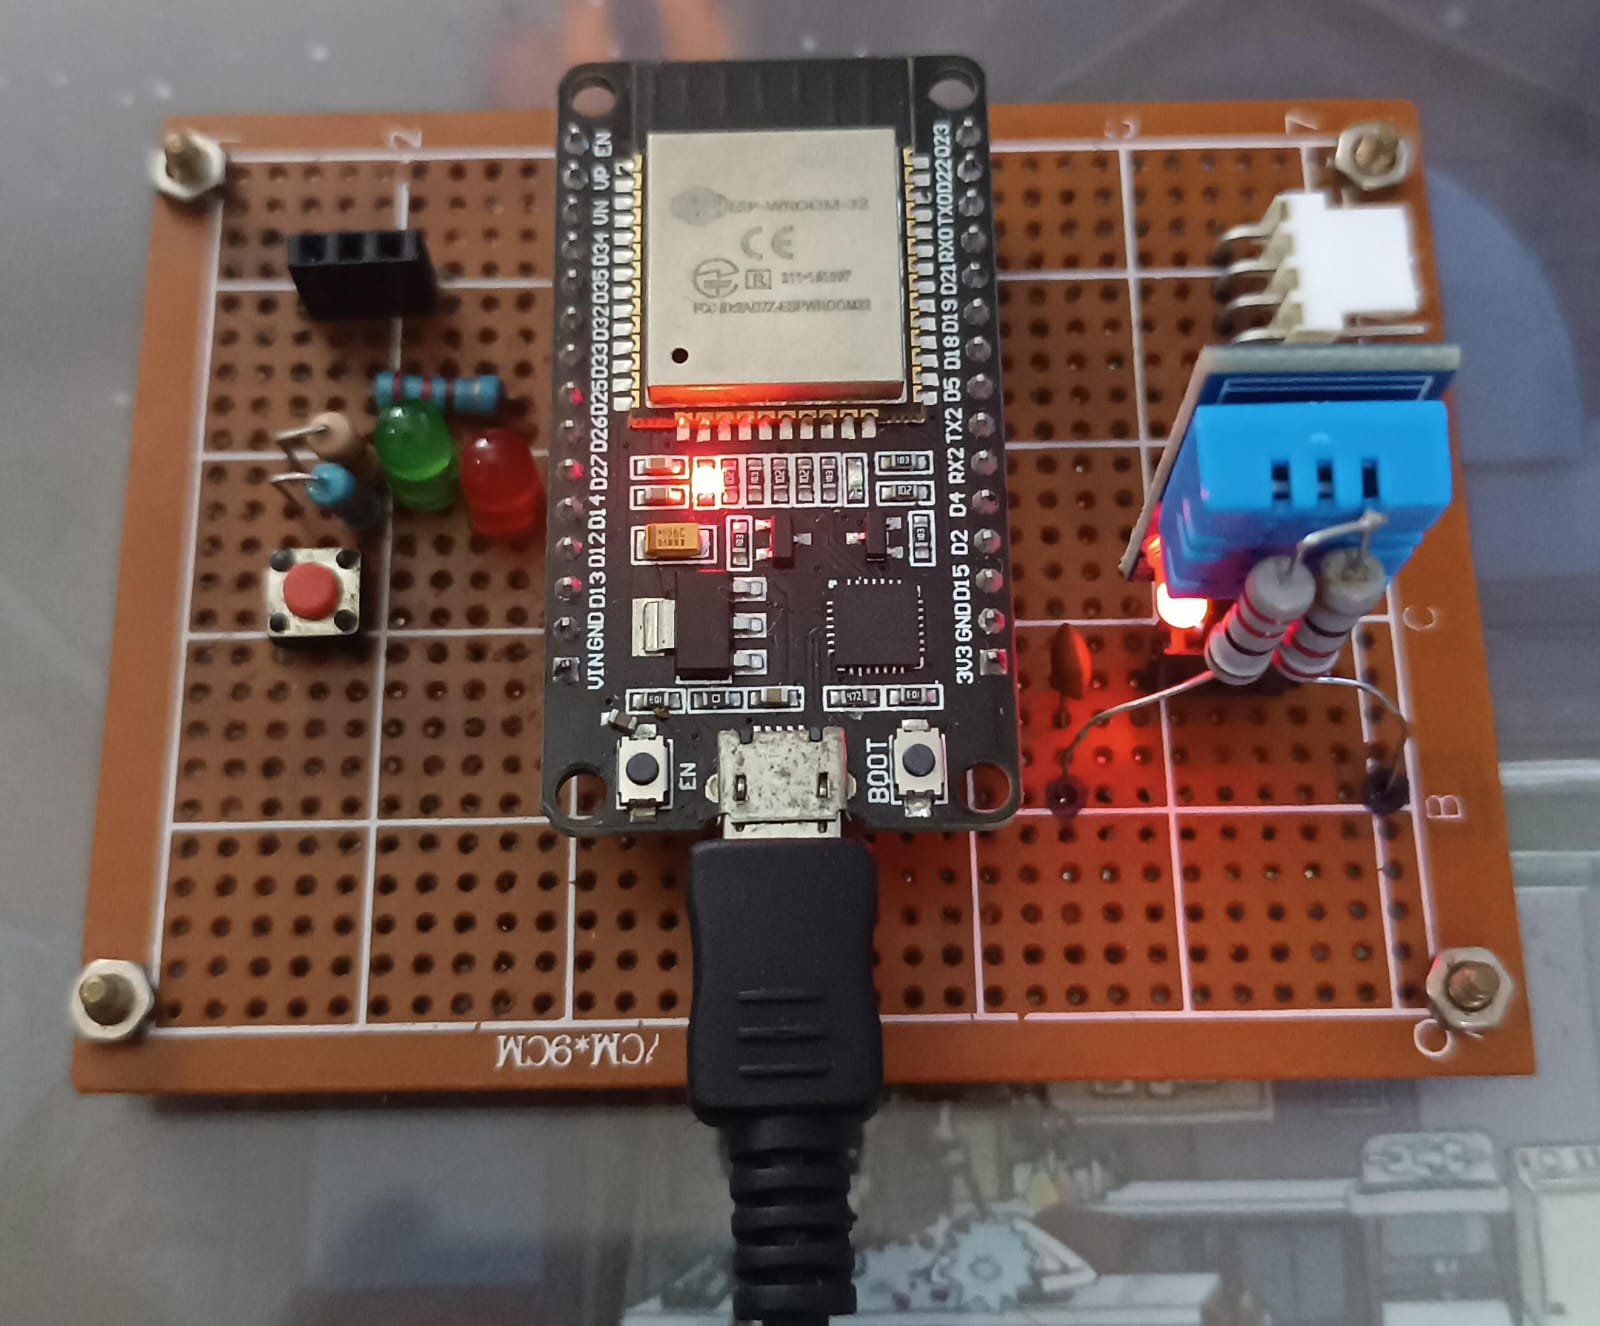

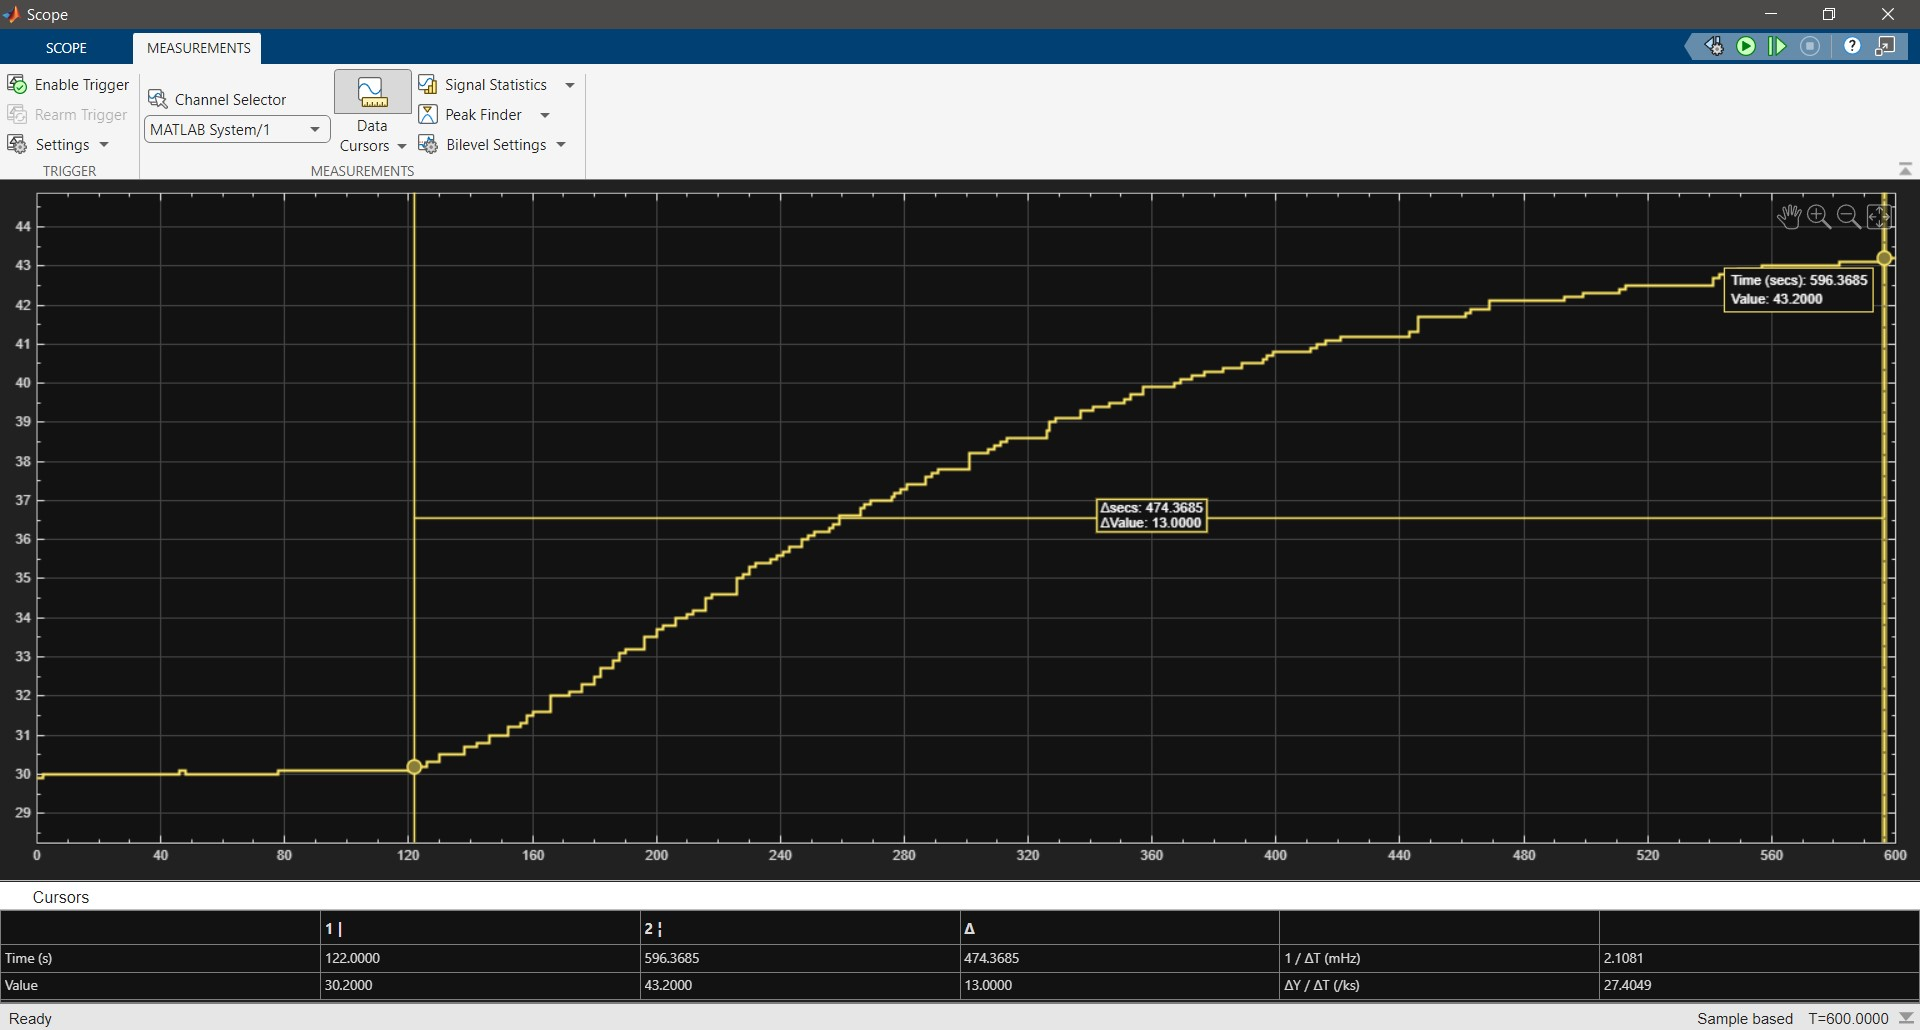

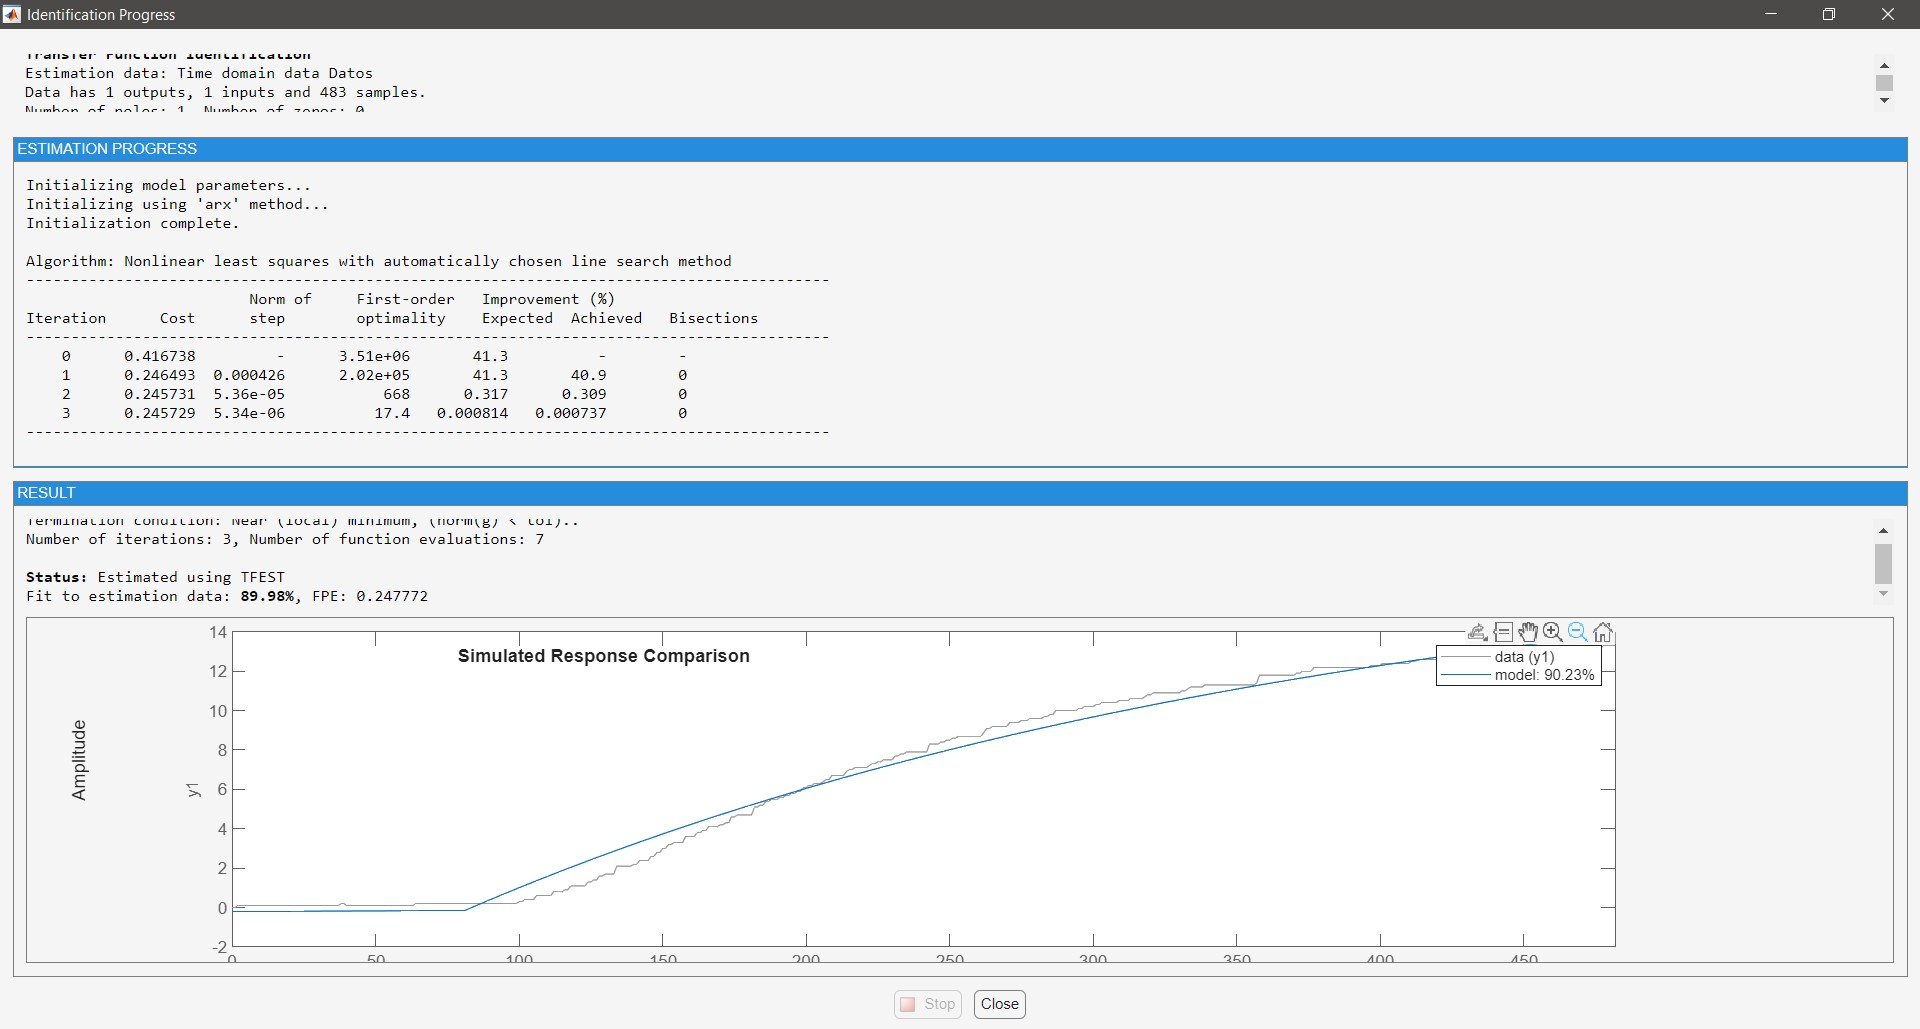

## 
$${\mathrm{P1D}\;\;\;\to \;\;\;G}_{P_1 } \left(\mathcal{s}\right)=P\left(\mathcal{s}\right)=\frac{0\ldotp 11864}{170\ldotp 65\cdot \mathcal{s}+1}\cdot e^{-30\cdot \mathcal{s}}$$


### `Ajuste de 90.23% > 80%`

### **Validación en Simulink:**

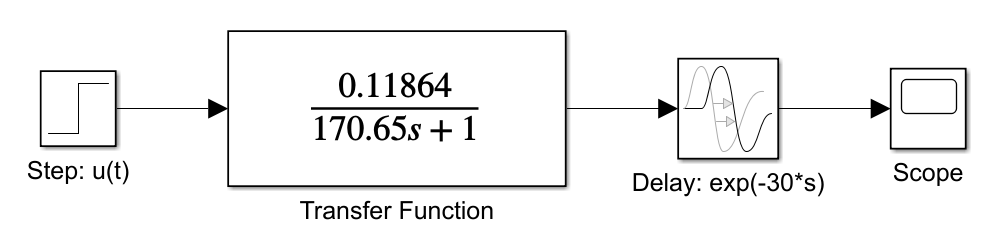

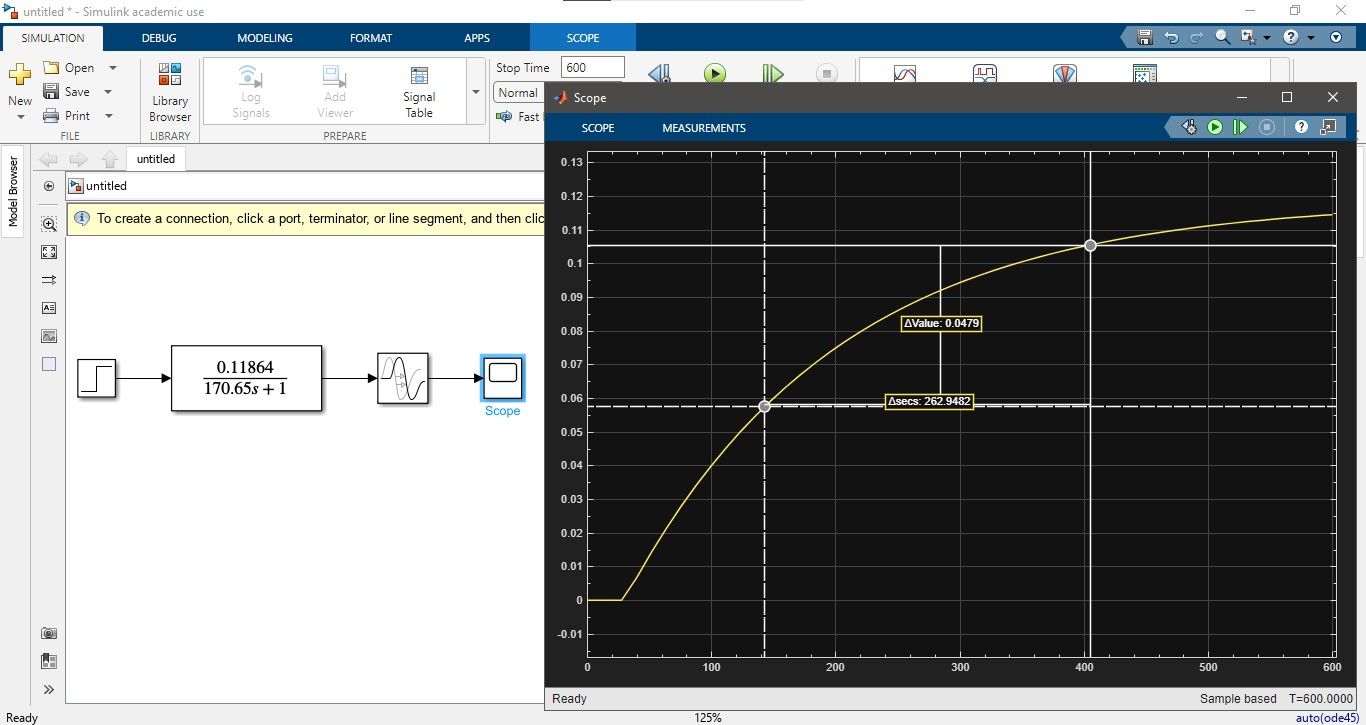

## 
$$G_P \left(\mathcal{s}\right)=\frac{0\ldotp 1144}{158\ldotp 7423\cdot \mathcal{s}+1}\cdot e^{-31\ldotp 7485\cdot \mathcal{s}}$$


#### $t_1 =L+\frac{1}{3}\cdot T=84\ldotp 6626\;\left\lbrack s\right\rbrack$**; **$t_2 =L+T=190\ldotp 4908\;\left\lbrack s\right\rbrack$** ;**

#### $\textrm{Ganancia}\;\;\to \;\;\;K=\frac{\Delta Y\;\left(\textrm{salida}\right)}{\Delta U\;\left(\textrm{entrada}\right)}=0\ldotp 1144$**; **

#### $\textrm{Constante}\;\textrm{de}\;\textrm{tiempo}\;\;\to \;\;\;T=\frac{3}{2}\left(t_2 -t_1 \right)=158\ldotp 7423\;\left\lbrack s\right\rbrack$**; **

#### 
$$\textrm{Retardo}\;\;\to \;\;\;L=t_2 -T=31\ldotp 7485\;\left\lbrack s\right\rbrack$$


### **A continuación se presenta el desarrollo para el respectivo deseño de los controladores P, PI, PD y PID:**

#### 
$$P\left(\mathcal{s}\right)=\frac{0\ldotp 11864}{170\ldotp 65\cdot \mathcal{s}+1}\cdot e^{-30\cdot \mathcal{s}}$$


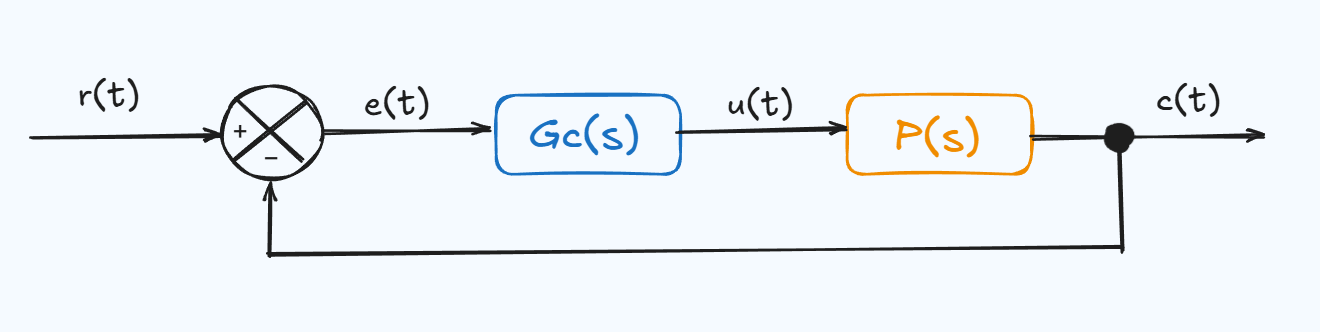

El siguiente procedimiento corresponde al cálculo del **controlador proporcional (P)**:

#### 
$$G_{\textrm{LC}} \left(\mathcal{s}\right)=\frac{C\left(\mathcal{s}\right)}{R\left(\mathcal{s}\right)}=\frac{G_C \left(\mathcal{s}\right)\cdot P\left(\mathcal{s}\right)}{1+G_C \left(\mathcal{s}\right)\cdot P\left(\mathcal{s}\right)}\approx \frac{\omega_n^2 }{{\mathcal{s}}^2 +2\cdot \zeta \cdot \omega_n \cdot \mathcal{s}+\omega_n^2 }$$



$$G_C \left(\mathcal{s}\right)=\frac{U\left(\mathcal{s}\right)}{E\left(\mathcal{s}\right)}=K\frac{\left(\mathcal{s}+z_1 \right)\cdot \left(\mathcal{s}+z_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+z_m \right)}{\left(\mathcal{s}+p_1 \right)\cdot \left(\mathcal{s}+p_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+p_n \right)}\;\;\to \;\;\textrm{Función}\;\textrm{de}\;\textrm{Transferencia}\;\textrm{del}\;\textrm{Controlador}\;\textrm{Generalizada}$$



$$P\left(\mathcal{s}\right)=\frac{N\left(\mathcal{s}\right)}{D\left(\mathcal{s}\right)}\;\;\to \;\;\textrm{Función}\;\textrm{de}\;\textrm{Transferencia}\;\textrm{del}\;\textrm{Sistema}\;o\;\textrm{Planta}$$



$$G_{\textrm{LC}} \left(\mathcal{s}\right)=\frac{C\left(\mathcal{s}\right)}{R\left(\mathcal{s}\right)}=\frac{K\frac{\left(\mathcal{s}+z_1 \right)\cdot \left(\mathcal{s}+z_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+z_m \right)}{\left(\mathcal{s}+p_1 \right)\cdot \left(\mathcal{s}+p_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+p_n \right)}\cdot \frac{N\left(\mathcal{s}\right)}{D\left(\mathcal{s}\right)}\;\;}{1+K\frac{\left(\mathcal{s}+z_1 \right)\cdot \left(\mathcal{s}+z_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+z_m \right)}{\left(\mathcal{s}+p_1 \right)\cdot \left(\mathcal{s}+p_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+p_n \right)}\cdot \frac{N\left(\mathcal{s}\right)}{D\left(\mathcal{s}\right)}\;\;}$$


#### 
$$G_{\textrm{LC}} \left(\mathcal{s}\right)=\frac{K\cdot \left(\mathcal{s}+z_1 \right)\cdot \left(\mathcal{s}+z_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+z_m \right)\cdot N\left(\mathcal{s}\right)\;\;}{\left(\mathcal{s}+p_1 \right)\cdot \left(\mathcal{s}+p_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+p_n \right)\cdot D\left(\mathcal{s}\right)+K\cdot \left(\mathcal{s}+z_1 \right)\cdot \left(\mathcal{s}+z_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+z_m \right)\cdot N\left(\mathcal{s}\right)}$$



$$\frac{K\cdot \left(\mathcal{s}+z_1 \right)\cdot \left(\mathcal{s}+z_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+z_m \right)\cdot N\left(\mathcal{s}\right)\;\;}{\left(\mathcal{s}+p_1 \right)\cdot \left(\mathcal{s}+p_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+p_n \right)\cdot D\left(\mathcal{s}\right)+K\cdot \left(\mathcal{s}+z_1 \right)\cdot \left(\mathcal{s}+z_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+z_m \right)\cdot N\left(\mathcal{s}\right)}\approx \frac{\omega_n^2 }{{\mathcal{s}}^2 +2\cdot \zeta \cdot \omega_n \cdot \mathcal{s}+\omega_n^2 }$$



$$\left(\mathcal{s}+p_1 \right)\cdot \left(\mathcal{s}+p_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+p_n \right)\cdot D\left(\mathcal{s}\right)+K\cdot \left(\mathcal{s}+z_1 \right)\cdot \left(\mathcal{s}+z_2 \right)\;\ldotp \ldotp \ldotp \;\left(\mathcal{s}+z_m \right)\cdot N\left(\mathcal{s}\right)\approx {\mathcal{s}}^2 +2\cdot \zeta \cdot \omega_n \cdot \mathcal{s}+\omega_n^2$$


## 
$$\left(170\ldotp 65\cdot \mathcal{s}+1\right)+K_P \cdot \left(0\ldotp 11864\cdot e^{-30\cdot \mathcal{s}} \right)={\mathcal{s}}^2 +2\cdot \zeta \cdot \omega_n \cdot \mathcal{s}+\omega_n^2$$


El término $e^{-30\cdot s}$ no se puede igualar directamente con los coeficientes, ya que la parte izquierda de la igualación, en su forma actual, tiene un "orden infinito" debido a la exponencial. Una solución a este inconveniente es **aproximar el retardo** con una **"aproximación racional"**, es decir, una fraccción de dos polinomios. La más común y utilizada es la **APROXIMACIÓN DE PADÉ **de primer orden.

Cabe resaltar que si se usa un orden mayor en la aproximación de Padé, también aumenta el orden del polinomio resultante para hacer la respectiva igualación.

### 
$$e^{-\theta \cdot \mathcal{s}} \approx \frac{1-\frac{\theta }{2}\cdot \mathcal{s}}{1+\frac{\theta }{2}\cdot \mathcal{s}}\;\;\;\to \;\;\;e^{-30\cdot \mathcal{s}} =\frac{1-\frac{30}{2}\cdot \mathcal{s}}{1+\frac{30}{2}\cdot \mathcal{s}}=\frac{1-15\cdot \mathcal{s}}{1+15\cdot \mathcal{s}}$$


Entonces se obtiene lo siguiente:

### 
$$\left(170\ldotp 65\cdot \mathcal{s}+1\right)+K_P \cdot \left(0\ldotp 11864\cdot \left(\frac{1-15\cdot \mathcal{s}}{1+15\cdot \mathcal{s}}\right)\right)={\mathcal{s}}^2 +2\cdot \zeta \cdot \omega_n \cdot \mathcal{s}+\omega_n^2$$


Operando la parte izquierda se obtiene lo siguiente:

#### 
$${\mathcal{s}}^2 +\left(0\ldotp 07253-0\ldotp 00069\cdot K_P \right)\cdot \mathcal{s}+\left(0\ldotp 0003907+0\ldotp 0000463\cdot K_P \right)={\mathcal{s}}^2 +2\cdot \zeta \cdot \omega_n \cdot \mathcal{s}+\omega_n^2$$


Se hacen las respectivas igualaciones:

#### 
$$2\cdot \zeta \cdot \omega_n =0\ldotp 07253-0\ldotp 00069\cdot K_P$$


#### 
$$\zeta \cdot \omega_n =0\ldotp 03627-0\ldotp 00035\cdot K_P$$


Se definen y calculan parámetros para el diseño del controlador y poder despejar la primera igualación:

#### 
$$P\textrm{arámetro}\;\textrm{que}\;\textrm{se}\;\textrm{asume}\;\textrm{para}\;\textrm{el}\;\textrm{diseño}\;\textrm{del}\;\textrm{controlador}\;\;\;\to \;\;\;\textrm{OV}\;\left(\textrm{Overshoot}\right)\le 20\;%$$


#### 
$$\zeta \;\;\;\;\to \;\;\;\;\textrm{Factor}\;\textrm{de}\;\textrm{Amortiguamiento}$$


### 
$$\zeta \ge \sqrt{\frac{{\ln \left(\textrm{OV}\right)}^2 }{\pi^2 +{\ln \left(\textrm{OV}\right)}^2 }}\;\;\;\;\to \;\;\;\;\zeta =0\ldotp 456$$


#### 
$$\zeta <1\;\;\;\;\to \;\;\;\textrm{Subamortiguado}$$


### 
$$t_{s\left(2%\right)} =\frac{4}{\zeta \cdot \omega_n }\;\;\;\;\to \;\;\textrm{Tiempo}\;\textrm{de}\;\textrm{Establecimiento}$$


Ahora, se puede despejar $\omega_n$ y obtener una `Ecuación #1`:

#### 
$$\zeta \cdot \omega_n =0\ldotp 03627-0\ldotp 00035\cdot K_P$$


#### 
$$\left(0\ldotp 456\right)\cdot \omega_n =0\ldotp 03627-0\ldotp 00035\cdot K_P$$


#### 
$$\omega_n =0\ldotp 03627-0\ldotp 00035\cdot K_P \;\;\;\;\to \;\;\;\;\textrm{Ecuación}\;\textrm{#1}$$


Finalmente, se hace la última igualación y obtener una `Ecuación #2`:

#### 
$$\omega_n^2 =0\ldotp 0003907-0\ldotp 0000463\cdot K_P \;\;\;\;\to \;\;\;\;\textrm{Ecuación}\;\textrm{#2}$$


El siguiente paso es **reemplazar **la `Ecuación #1` en la `Ecuación #2`, agrupar términos semejantes y **despejar** la respectiva constante **(**$K_P$**) **del controlador, haciendo las respectivas operaciones se obtiene lo siguiente:

### 
$${\left(0\ldotp 07954-0\ldotp 00077{\cdot K}_P \right)}^2 =0\ldotp 0003907+0\ldotp 0000463\cdot K_P$$


### 
$$K_{P_1 } =243\ldotp 5872$$


### 
$$K_{P_2 } =41\ldotp 1009$$


Se usa la `Ecuación #2 `para obtener $\omega_n$:

### 
$$\omega_{n_1 } =0\ldotp 10802\;\frac{\textrm{rad}}{s}$$


### 
$$\omega_{n_2 } =0\ldotp 04789\;\frac{\mathrm{rad}}{s}$$


Por último, se puede calcular el **Tiempo de Establecimiento**:

### 
$${t_{s\left(2%\right)} }_1 =81\ldotp 20653\;\left\lbrack s\right\rbrack$$


### 
$${t_{s\left(2%\right)} }_2 =183\ldotp 1683\;\left\lbrack s\right\rbrack$$


### **El siguiente paso a realizar corresponde a la validación en SIMULINK, la sintonización del controlador usandola teoría de Ziegler-Nichols  y el uso de una herramienta para sintonizar el controlador de forma más "automática" y realizar las respectivas comparaciones. Finalmente, se recalca que este sería el mismo procedimiento a realizar para el diseño de otro controlador de forma ****analítica****.**

### `El siguiente código se usa para el diseño y comparación de los diferentes controladores diseñados:`

% Hecho por: Diego Andrés García Díaz.
% Código: 2195533.
% Fecha: 24/09/2025.
% Asignatura: Control II (Adelanto de Nota).
% 
% ------------------------------------------------------------------------------
% -------------- Diseño Controladores para Control de Temperatura --------------
% ------------------------------------------------------------------------------

% Esta sección borra la ventana de comandos, el espacio de trabajo y cierra 
% cualquier figura abierta. También define s como una variable de función de
% transferencia para su uso posterior.
clc; clear; close all;
s = tf('s');

% Definición de parámetros del sistema (Planta) identificada
Kp = 0.11864;   % Ganancia del sistema
Tp1 = 170.65;  % Tiempo de establecimiento
L = 30;    % Tiempo muerto o Delay

% Función de Transferencia del modelo identificado (Actuador + Plata + Sensor)
P_s = ( (Kp * exp(-L*s) ) / ((Tp1*s) + 1) )  


P_s =
 
                 0.1186
  exp(-30*s) * -----------
               170.7 s + 1
 
Continuous-time transfer function.


% Función de Transferencia factorizada
P_s_fact = zpk(P_s)


P_s_fact =
 
               0.00069522
  exp(-30*s) * -----------
               (s+0.00586)
 
Continuous-time zero/pole/gain model.



% Abrir 'sisotool' para el diseño y análisis de los controladores
% sisotool(P_s)

## **Usando el método de Ziegler-Nichols:**

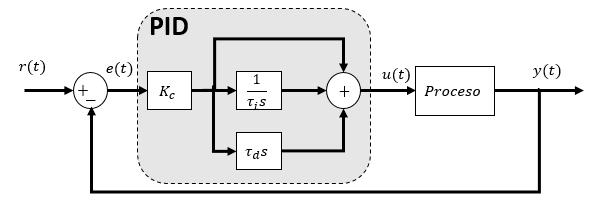

## 
$$G_{C_{\textrm{PID}} } \left(\mathcal{s}\right)=K_p \left(1+\frac{1}{T_i \cdot \mathcal{s}}+T_d \cdot \mathcal{s}\right)$$


### $K_i =\frac{K_p }{T_i }$      ;    $K_d =K_p \cdot T_d$

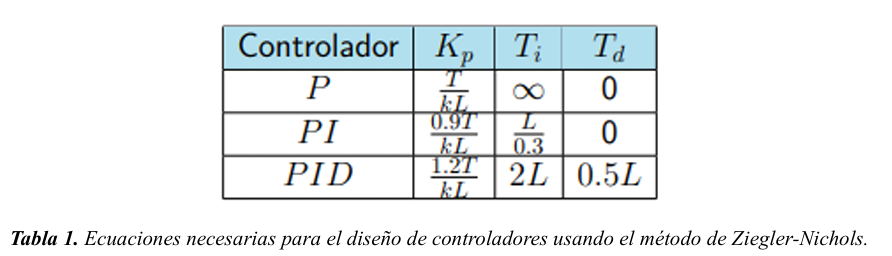

## Controlador Proporcional (P)

### 
$$G_{C_P } \left(\mathcal{s}\right)=K_p$$


clc; clear; close all;
s = tf('s');

Kp = 0.11864;  % Ganancia del sistema
Tp1 = 170.65;  % Tiempo de establecimiento
L = 30;        % Tiempo muerto o Delay

% P_s = ( (Kp * exp(-L*s) ) / ((Tp1*s) + 1) ) 

% ----- Aproximación de Padé del retardo -----
[num, den] = pade(L, 1);   % 1er orden (> 2 si desea más precisión)
Delay = tf(num, den)


Delay =
 
  -s + 0.06667
  ------------
  s + 0.06667
 
Continuous-time transfer function.



% ----- Planta aproximada -----
P_s = Kp * Delay / (Tp1*s + 1)


P_s =
 
      -0.1186 s + 0.007909
  -----------------------------
  170.7 s^2 + 12.38 s + 0.06667
 
Continuous-time transfer function.



% Parámetros del Criterio de Ziegler-Nichols para controlador P
kp_ZN = (Tp1)/(Kp*L); % Cálculo de la ganancia proporcional del controlador P
Ti_ZN = inf;
Td_ZN = 0;

% Función de transferencia controlador
Gc_P1 = 10 % Ganancia proporcional del controlador P, aleatoria

Gc_P1 = 10

Gc_P2 = kp_ZN % Ganancia proporcional del controlador P, método Z-N

Gc_P2 = 47.9462

Gc_P3 = 41.1009 % Ganancia proporcional del controlador P, método analítico

Gc_P3 = 41.1009

Gc_P4 = 68 % Ganancia proporcional del controlador P, aleatoria

Gc_P4 = 68

Gc_Pmax = 104.3 % Ganancia proporcional del controlador P, método "prueba y error"

Gc_Pmax = 104.3000


% Se cierra el lazo
T_cl1 = feedback((Gc_P1*P_s), 1);
T_cl2 = feedback((Gc_P2*P_s), 1);
T_cl3 = feedback((Gc_P3*P_s), 1);
T_cl4 = feedback((Gc_P4*P_s), 1);
T_clmax = feedback((Gc_Pmax*P_s), 1);

% Se grafica la respuesta
t = 0:1:600;
isstable(T_cl1)     % Se verifica la estabilidad del sistema

ans = logical
   1


isstable(T_cl2)     % Se verifica la estabilidad del sistema

ans = logical
   1


isstable(T_cl3)     % Se verifica la estabilidad del sistema

ans = logical
   1


isstable(T_cl4)     % Se verifica la estabilidad del sistema

ans = logical
   1


isstable(T_clmax)   % Se verifica la estabilidad del sistema

ans = logical
   1


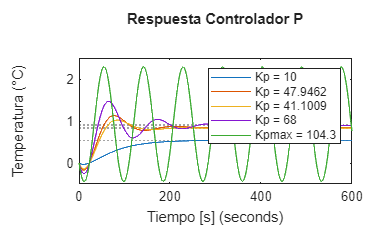

figure(1);
step(T_cl1, T_cl2, T_cl3, T_cl4, T_clmax, t); 
legend('Kp = 10','Kp = 47.9462','Kp = 41.1009','Kp = 68','Kpmax = 104.3');
% grid on;
title('Respuesta Controlador P');
xlabel('Tiempo [s]');
ylabel('Temperatura (°C)');

## Controlador Proporcional-Integral (PI)

### 
$$G_{C_{\textrm{PI}} } \left(\mathcal{s}\right)=K_p \cdot \left(\frac{\mathcal{s}+z_1 }{s}\right)\;\;\;\;\to \;\;\;G_{C_{\textrm{PI}} } \left(\mathcal{s}\right)=K_p \cdot \left(\frac{1}{T_i \cdot \mathcal{s}}\right)\;$$


clc; clear; close all;
s = tf('s');

Kp = 0.11864;  % Ganancia del sistema
Tp1 = 170.65;  % Tiempo de establecimiento
L = 30;        % Tiempo muerto o Delay

% ----- Aproximación de Padé del retardo -----
[num, den] = pade(L, 1);   % 1er orden (> 2 si desea más precisión)
Delay = tf(num, den)


Delay =
 
  -s + 0.06667
  ------------
  s + 0.06667
 
Continuous-time transfer function.



% ----- Planta aproximada -----
P_s = Kp * Delay / (Tp1*s + 1)


P_s =
 
      -0.1186 s + 0.007909
  -----------------------------
  170.7 s^2 + 12.38 s + 0.06667
 
Continuous-time transfer function.



% Parámetros del Criterio de Ziegler-Nichols para controlador PI
kp_ZN = (0.9*Tp1)/(Kp*L) % Cálculo de la ganancia proporcional del controlador PI

kp_ZN = 43.1516

Ti_ZN = L/0.3

Ti_ZN = 100

Td_ZN = 0;

ki_ZN = kp_ZN / Ti_ZN % Cálculo de la ganancia integral del controlador PI

ki_ZN = 0.4315


% Función de transferencia controlador
% Gc_PI = kp_ZN * (1 + (1/(Ti_ZN * s)))   % Forma alternativa
Gc_PI2 = kp_ZN + (ki_ZN / s)    % Ganancias del controlador PI, método Z-N            


Gc_PI2 =
 
  43.15 s + 0.4315
  ----------------
         s
 
Continuous-time transfer function.


Gc_PI3 = 41.1009 + (0.88 / s)   % Ganancias del controlador PI, se asumen


Gc_PI3 =
 
  41.1 s + 0.88
  -------------
        s
 
Continuous-time transfer function.


Gc_PI4 = 13.3532 + (0.11534 / s)   % Ganancias del controlador PI, PID Tuner


Gc_PI4 =
 
  13.35 s + 0.1153
  ----------------
         s
 
Continuous-time transfer function.


Gc_PI5 = 39.2173 + (0.18749 / s) % Ganancias del controlador PI, PID Tuner


Gc_PI5 =
 
  39.22 s + 0.1875
  ----------------
         s
 
Continuous-time transfer function.


Gc_PI6 = -241.6 + (8.28 / s) % Ganancias del controlador PI, analíticamente 


Gc_PI6 =
 
  -241.6 s + 8.28
  ---------------
         s
 
Continuous-time transfer function.



% Se cierra el lazo
T_cl1 = feedback((Gc_PI2*P_s), 1);
T_cl2 = feedback((Gc_PI3*P_s), 1);
T_cl3 = feedback((Gc_PI4*P_s), 1);
T_cl4 = feedback((Gc_PI5*P_s), 1);
T_cl5 = feedback((Gc_PI6*P_s), 1); % (SISTEMA INESTABLE)
% pole(T_cl5)

ans =   -0.3000 + 0.0000i
   0.0297 + 0.0199i
   0.0297 - 0.0199i



% Se grafica la respuesta
t = 0:1:600;
isstable(T_cl1)   % Se verifica la estabilidad del sistema

ans = logical
   1


isstable(T_cl2)   % Se verifica la estabilidad del sistema

ans = logical
   1


isstable(T_cl3)   % Se verifica la estabilidad del sistema

ans = logical
   1


isstable(T_cl4)   % Se verifica la estabilidad del sistema

ans = logical
   1


isstable(T_cl5)   % Se verifica la estabilidad del sistema

ans = logical
   0


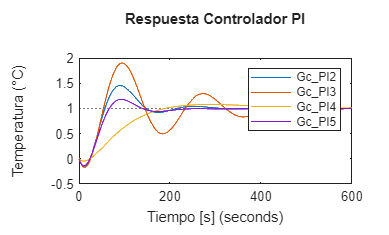

figure(2);
step(T_cl1, T_cl2, T_cl3, T_cl4, t)
legend('Gc_PI2','Gc_PI3','Gc_PI4','Gc_PI5');
title('Respuesta Controlador PI');
xlabel('Tiempo [s]');
ylabel('Temperatura (°C)');

## Controlador Proporcional-Derivativo (PD)

### 
$$G_{C_{\textrm{PD}} } \left(\mathcal{s}\right)=K_p \cdot \left(\mathcal{s}+z_1 \right)\;\;\;\;\to \;\;\;\;G_{C_{\textrm{PD}} } \left(\mathcal{s}\right)=K_p \cdot \left(T_d \cdot \mathcal{s}\right)$$


clc; clear; close all;
s = tf('s');

Kp = 0.11864;  % Ganancia del sistema
Tp1 = 170.65;  % Tiempo de establecimiento
L = 30;        % Tiempo muerto o Delay

% ----- Aproximación de Padé del retardo -----
[num, den] = pade(L, 1);   % 1er orden (> 2 si desea más precisión)
Delay = tf(num, den)


Delay =
 
  -s + 0.06667
  ------------
  s + 0.06667
 
Continuous-time transfer function.



% ----- Planta aproximada -----
P_s = Kp * Delay / (Tp1*s + 1)


P_s =
 
      -0.1186 s + 0.007909
  -----------------------------
  170.7 s^2 + 12.38 s + 0.06667
 
Continuous-time transfer function.



% Parámetros del Criterio de Ziegler-Nichols para controlador PD
kp_ZN = 57.5354

kp_ZN = 57.5354

Ti_ZN = 0

Ti_ZN = 0

Td_ZN = 863.0310

Td_ZN = 863.0310


kd_ZN = kp_ZN * Td_ZN % Cálculo de la ganancia derivativa del controlador PD

kd_ZN = 4.9655e+04


% Función de transferencia controlador
% Gc_PD = kp_ZN * (1 + (Td_ZN * s)0   % Forma alternativa
Gc_PD2 = kp_ZN + (kd_ZN * s)      % Ganancias del controlador PD, método Z-N


Gc_PD2 =
 
  4.965e04 s + 57.54
 
Continuous-time transfer function.


Gc_PD3 = 47.5354 + (600 * s)      % Ganancias del controlador PD, se asumen


Gc_PD3 =
 
  600 s + 47.54
 
Continuous-time transfer function.


Gc_PD4 = 13.3532 + (92.3444 * s)  % Ganancias del controlador PD, PID Tuner 


Gc_PD4 =
 
  92.34 s + 13.35
 
Continuous-time transfer function.


Gc_PD5 = 35.91 + (-102.8 * s)     % Ganancias del controlador PD, analíticamente 


Gc_PD5 =
 
  -102.8 s + 35.91
 
Continuous-time transfer function.




% Se cierra el lazo
T_cl1 = feedback((Gc_PD2*P_s), 1); % SISTEMA INESTABLE
T_cl2 = feedback((Gc_PD3*P_s), 1);
T_cl3 = feedback((Gc_PD4*P_s), 1);
T_cl4 = feedback((Gc_PD5*P_s), 1);
% zero(T_cl4)
% pole(T_cl4)

% Se grafica la respuesta
t = 0:1:600;
isstable(T_cl1)   % Se verifica la estabilidad del sistema

ans = logical
   0


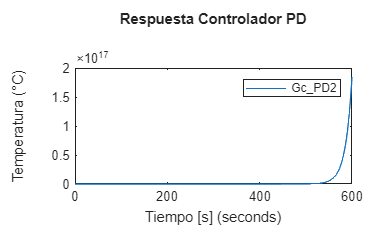

figure(2);
step(T_cl1, t)
legend('Gc_PD2');
title('Respuesta Controlador PD');
xlabel('Tiempo [s]');
ylabel('Temperatura (°C)');


isstable(T_cl2)   % Se verifica la estabilidad del sistema

ans = logical
   1


isstable(T_cl3)   % Se verifica la estabilidad del sistema

ans = logical
   1


isstable(T_cl4)   % Se verifica la estabilidad del sistema

ans = logical
   1


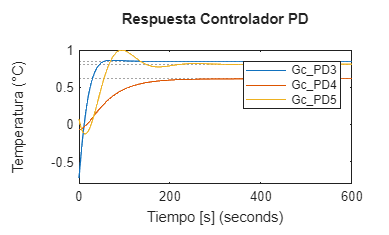

figure(3);
step(T_cl2, T_cl3, T_cl4, t)
legend('Gc_PD3','Gc_PD4','Gc_PD5');
title('Respuesta Controlador PD');
xlabel('Tiempo [s]');
ylabel('Temperatura (°C)');

## Controlador Proporcional-Integral-Derivativo (PID)

#### 
$$G_{C_{\textrm{PID}} } \left(\mathcal{s}\right)=K_p \cdot \left(\frac{\left(\mathcal{s}+z_1 \right)\cdot \left(\mathcal{s}+z_2 \right)}{s}\right)\;\;\;\;\to \;\;\;\;G_{C_{\textrm{PID}} } \left(\mathcal{s}\right)=K_p \cdot \left(1+\frac{1}{T_i \cdot \mathcal{s}}+T_d \cdot \mathcal{s}\right)$$


clc; clear; close all;
s = tf('s');

Kp = 0.11864;  % Ganancia del sistema
Tp1 = 170.65;  % Tiempo de establecimiento
L = 30;        % Tiempo muerto o Delay

% ----- Aproximación de Padé del retardo -----
[num, den] = pade(L, 1);   % 1er orden (> 2 si desea más precisión)
Delay = tf(num, den)


Delay =
 
  -s + 0.06667
  ------------
  s + 0.06667
 
Continuous-time transfer function.



% ----- Planta aproximada -----
P_s = Kp * Delay / (Tp1*s + 1)


P_s =
 
      -0.1186 s + 0.007909
  -----------------------------
  170.7 s^2 + 12.38 s + 0.06667
 
Continuous-time transfer function.



% Parámetros del Criterio de Ziegler-Nichols para controlador PID
kp_ZN = (1.2*Tp1)/(Kp*L)

kp_ZN = 57.5354

Ti_ZN = 2*L;
Td_ZN = 0.5*L;

ki_ZN = kp_ZN / Ti_ZN % Cálculo de la ganancia integral del controlador PID

ki_ZN = 0.9589

kd_ZN = kp_ZN * Td_ZN % Cálculo de la ganancia derivativa del controlador PID

kd_ZN = 863.0310


% Función de transferencia controlador
% Gc_PID = kp_ZN * ( 1 + (1/(Ti_ZN * s)) + (Td_ZN * s) )   % Forma alternativa
Gc_PID2 = kp_ZN + (ki_ZN / s) + (kd_ZN * s)


Gc_PID2 =
 
  863 s^2 + 57.54 s + 0.9589
  --------------------------
              s
 
Continuous-time transfer function.


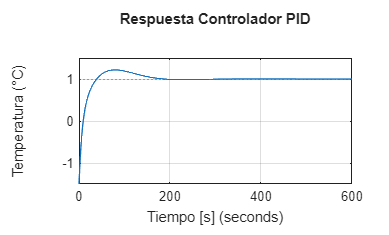


% Se cierra el lazo
T_cl = feedback((Gc_PID2*P_s), 1);

% Se grafica la respuesta
t = 0:1:600;
isstable(T_cl);   % Se verifica la estabilidad del sistema
figure(3);
step(T_cl, t)
grid on;
title('Respuesta Controlador PID');
xlabel('Tiempo [s]');
ylabel('Temperatura (°C)');

## Diseño de controladores de forma "automatizada"

#### **pid(Kp,Ki,Kd)**, **sisotool **y **PID Tuner**

clc; clear; close all;
% s = tf('s');

Kp = 0.11864;  % Ganancia del sistema
Tp1 = 170.65;  % Tiempo de establecimiento
L = 30;        % Tiempo muerto o Delay

% Se diseñan diferentes tipos de controladores utilizando los parámetros 
% calculados de Ziegler-Nichols. Además, se usa la función 'pid(Kp,Ki,Kd)'.

% Parámetros del Criterio de Ziegler-Nichols para controlador PID
kp_ZN = (1.2*Tp1)/(Kp*L)

kp_ZN = 57.5354

Ti_ZN = 2*L

Ti_ZN = 60

Td_ZN = 0.5*L

Td_ZN = 15


ki_ZN = kp_ZN / Ti_ZN % Cálculo de la ganancia integral del controlador PID

ki_ZN = 0.9589

kd_ZN = kp_ZN * Td_ZN % Cálculo de la ganancia derivativa del controlador PID

kd_ZN = 863.0310


% Se crean un controlador proporcional (C_p), un controlador PI (C_pi), un 
% controlador PD (C_pd) y un controlador PID (C_pid).

% Controlador P
C_p = pid(kp_ZN, 0, 0)


C_p =
 
  Kp = 57.5
 
P-only controller.



% Controlador PI
C_pi = pid(kp_ZN, ki_ZN, 0)


C_pi =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 57.5, Ki = 0.959
 
Continuous-time PI controller in parallel form.



% Controlador PD
C_pd = pid(kp_ZN, 0, kd_ZN)


C_pd =
 
             
  Kp + Kd * s
             

  with Kp = 57.5, Kd = 863
 
Continuous-time PD controller in parallel form.


% sirve = isproper(C_pd)

% Controlador PID
C_pid = pid(kp_ZN, ki_ZN, kd_ZN)


C_pid =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 57.5, Ki = 0.959, Kd = 863
 
Continuous-time PID controller in parallel form.


% Finalmente, los controladores continuos se convierten a sus formatos digitales 
% utilizando un tiempo de muestreo (Ts) especificado. 
% Para esta conversión se utiliza la función c2d con el método 'zoh' (retención 
% de orden cero), lo que hace que los controladores sean adecuados para su 
% implementación en sistemas de control digital.

% Controladores digitales (suponiendo un muestreo de Ts)
Ts = 1;   % Tiempo de muestreo

C_p_digital = c2d(C_p, Ts, 'zoh')      % P


C_p_digital =
 
  Kp = 57.5
 
P-only controller.


C_p_digitall = c2d(C_p, Ts, 'tustin')      % P


C_p_digitall =
 
  Kp = 57.5
 
P-only controller.


C_pi_digital = c2d(C_pi, Ts, 'zoh')    % PI


C_pi_digital =
 
              Ts  
  Kp + Ki * ------
              z-1 

  with Kp = 57.5, Ki = 0.959, Ts = 1
 
Sample time: 1 seconds
Discrete-time PI controller in parallel form.


% C_pd_digital = c2d(C_pd, Ts, 'zoh')    % PD
% C_pid_digital = c2d(C_pid, Ts, 'zoh')  % PID


% Abrir 'sisotool' para el diseño y análisis de los controladores
% sisotool()
